# roll-pitch-yaw rotation

close all;
clear;
clc;

## read model

TR = stlread("cube.stl");

model.Vertices = TR.Points;
model.Faces = TR.ConnectivityList;

xaxis = [[0,0,0]', [2,0,0]'];
yaxis = [[0,0,0]', [0,2,0]'];
zaxis = [[0,0,0]', [0,0,2]'];

vertices_base = model.Vertices';

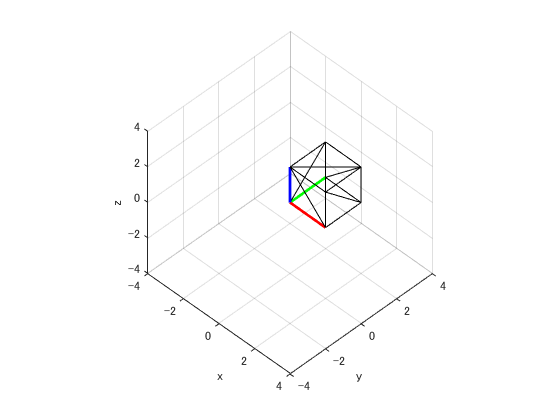

figure;
axis equal;
grid on;
hold on;

patch(model, 'FaceColor', 'none');
plot3(xaxis(1,:), xaxis(2,:), xaxis(3,:), 'Color', 'red', 'LineWidth', 2);
plot3(yaxis(1,:), yaxis(2,:), yaxis(3,:), 'Color', 'green', 'LineWidth', 2);
plot3(zaxis(1,:), zaxis(2,:), zaxis(3,:), 'Color', 'blue', 'LineWidth', 2);

% ranges
xlim([-4, 4]);
ylim([-4, 4]);
zlim([-4, 4]);

% labels
xlabel("x");
ylabel("y");
zlabel("z");

% view angle
view([45, 45]);

## rotate model

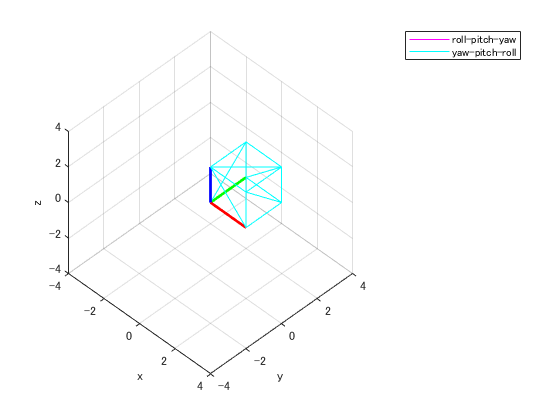

r = 0;
p = 0;
y = 0;

figure;
axis equal;
grid on;
hold on;

% ranges
xlim([-4, 4]);
ylim([-4, 4]);
zlim([-4, 4]);

% labels
xlabel("x");
ylabel("y");
zlabel("z");

% view angle
view([45, 45]);

% roll-pitch-yaw rotation
vertices = yaw(y) * pitch(p) * roll(r) * vertices_base;
model.Vertices = vertices';
patch(model, 'EdgeColor', 'magenta', 'FaceColor', 'none');

% yaw-pitch-roll rotation
vertices = roll(r) * pitch(p) * yaw(y) * vertices_base;
model.Vertices = vertices';
patch(model, 'EdgeColor', 'cyan', 'FaceColor', 'none');

% axes
plot3(xaxis(1,:), xaxis(2,:), xaxis(3,:), 'Color', 'red', 'LineWidth', 2);
plot3(yaxis(1,:), yaxis(2,:), yaxis(3,:), 'Color', 'green', 'LineWidth', 2);
plot3(zaxis(1,:), zaxis(2,:), zaxis(3,:), 'Color', 'blue', 'LineWidth', 2);

legend(["roll-pitch-yaw", "yaw-pitch-roll"])